set(0,'DefaultAxesFontSize',24,'DefaultAxesFontName','Times New Roman');
set(0,'DefaultTextFontSize',24,'DefaultTextFontName','Times New Roman');

x = [5,7,9,11,13];
y = [1.24875, 1.610625, 1.89125, 2.336428571, 4.683];

plf = polyfit(x(1:end-1), y(1:end-1), 1)

plf =     0.1772    0.3543


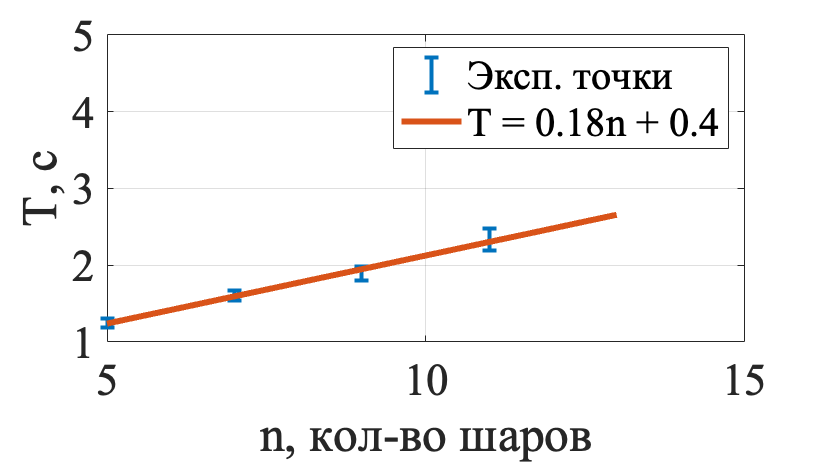

y_new = polyval(plf, x);
errors = [0.05515625, 0.066875, 0.0928125, 0.137857143, 0];

fig1 = figure(Position=[0 0 1280 720]);
errorbar(x,y,errors, 'LineStyle','none', LineWidth=2);
hold on
plot(x, y_new, LineWidth=3);
legend('Эксп. точки', 'T = 0.18n + 0.4')
grid on
xlabel('n, кол-во шаров');
ylabel('T, с');
saveas(fig1, 'plot1.png');

b_h = 4*pi^2/0.18^2 * (0.8342*0.3^2)/(3*74.7)

b_h = 0.4082

x = [4,6,8,10];
y = [0.114, 0.1836, 0.2088, 0.2136];
y = y*960;

plf = polyfit(x, y, 1)

plf =    15.5520   63.9360


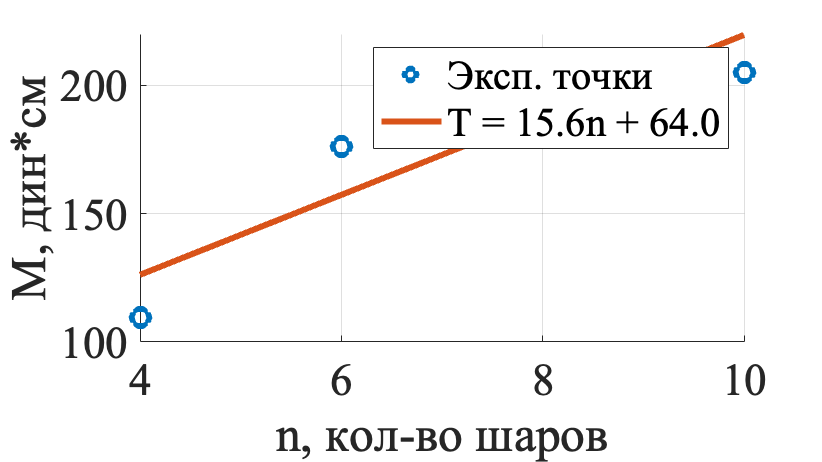

y_new = polyval(plf, x);

fig2 = figure(Position=[0 0 1280 720]);
scatter(x,y, 80, LineWidth=3);
grid on
hold on
plot(x, y_new, LineWidth=3);
xlabel('n, кол-во шаров');
ylabel('M, дин*см');
legend('Эксп. точки', 'T = 15.6n + 64.0')
saveas(fig2, 'plot2.png');

b_v = 15.6/74.7

b_v = 0.2088

b = sqrt(b_v^2 + b_h^2)

b = 0.4585

beta = atand(b_h/b_v)

beta = 62.9064

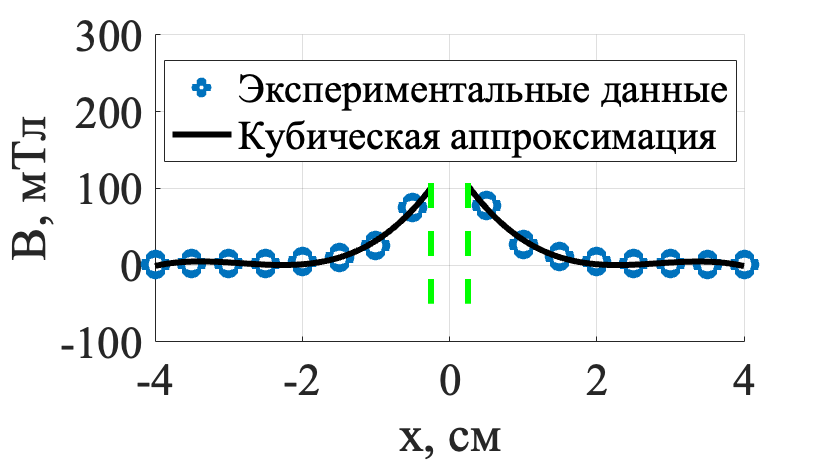

x = [-4
-3.5
-3
-2.5
-2
-1.5
-1
-0.5
-0.25
0.25
0.5
1
1.5
2
2.5
3
3.5
4]';

y = [1
1.8
1.8
2.6
5.2
10.4
25.9
75.2
204.5
226.5
77.6
26.4
11.2
5.2
2.6
1.8
1.3
1]';

x_new_left = linspace(-4, -0.25, 100);
plf_left = polyfit(x(1:8), y(1:8), 3);
y_new_left = polyval(plf_left, x_new_left);

x_new_rigth = linspace(0.25, 4, 100);
plf_rigth = polyfit(x(11:end), y(11:end), 3);
y_new_rigth = polyval(plf_rigth, x_new_rigth);

fig3 = figure(Position=[0 0 1280 720]);
scatter(x,y,120,LineWidth=4);
grid on
hold on
plot(x_new_left, y_new_left, LineWidth=3, color='black');
hold on
plot(x_new_rigth, y_new_rigth, LineWidth=3, color='black');
hold on 
plot([-0.25, -0.25], [-50, 250], LineStyle="--", LineWidth=3, Color='green');
hold on
plot([0.25, 0.25], [-50, 250], LineStyle="--", LineWidth=3, Color='green');
xlabel('x, см');
ylabel('B, мТл');
legend('Экспериментальные данные', 'Кубическая аппроксимация', Location='best');
saveas(fig3, 'plot3.png');

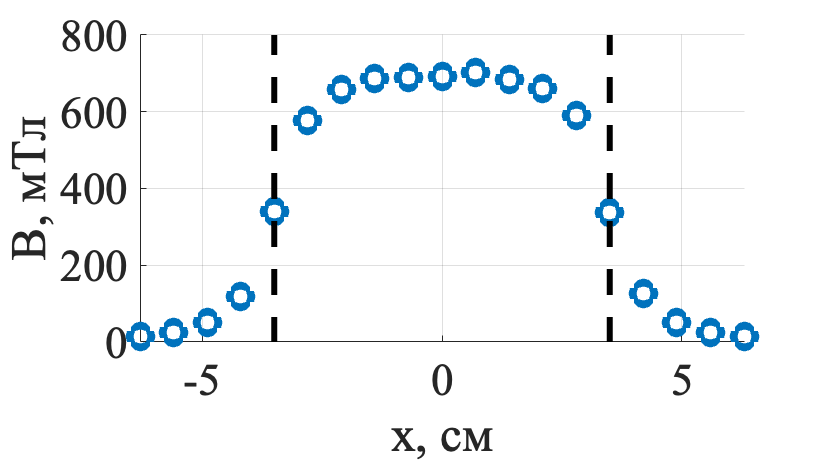

x = [-6.3
-5.6
-4.9
-4.2
-3.5
-2.8
-2.1
-1.4
-0.7
0
0.7
1.4
2.1
2.8
3.5
4.2
4.9
5.6
6.3]';

y = [13.6
25.2
50.6
118.3
341.2
577.4
659
685.5
689.4
691
701
682.8
661.3
589.2
337.3
125.4
49.8
24.9
13.4]';

x_free = linspace(-8, 8, 300);
const = 0;
y_free = 
fig4 = figure(Position=[0 0 1280 720]);
scatter(x,y,120, LineWidth=4);
grid on
hold on
plot([-3.5, -3.5], [0, 800], LineWidth=3, LineStyle="--", color = 'black');
hold on
plot([3.5, 3.5], [0, 800], LineWidth=3, LineStyle="--",color = 'black');
xlabel('x, см');
ylabel('B, мТл');
saveas(fig4, 'plot4.png');